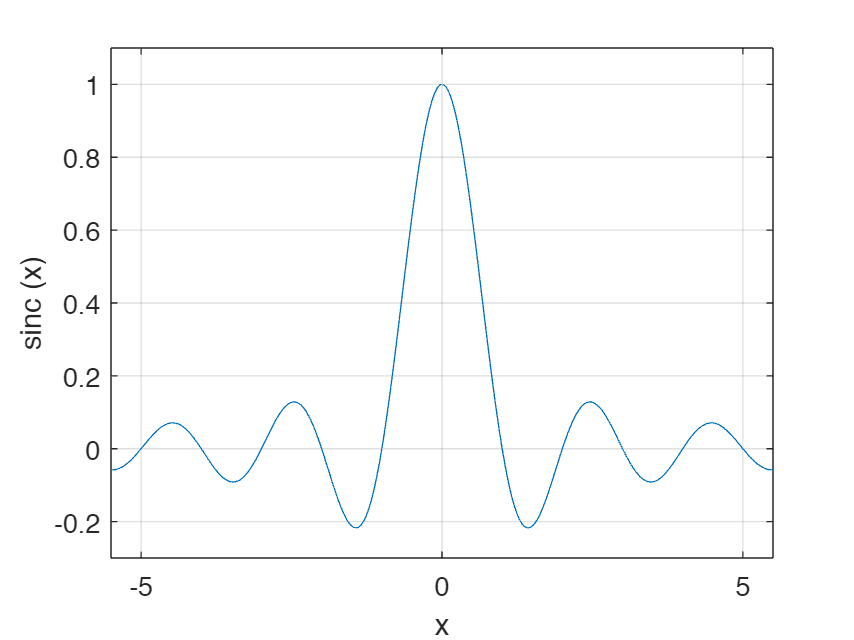

 
% Plot_sinc.m Plotting of sinc(x) function 
clc;
clear;
close all;

x= -5.5:0.01:5.5;
sinc=sin(pi*x)./(pi*x);
plot(x,sinc);
axis([-5.5 5.5 -0.3 1.1]); 
grid on;
xlabel('x'); 
ylabel('sinc (x)');

# Fourier Transform of rect(x,y) plus MATLAB

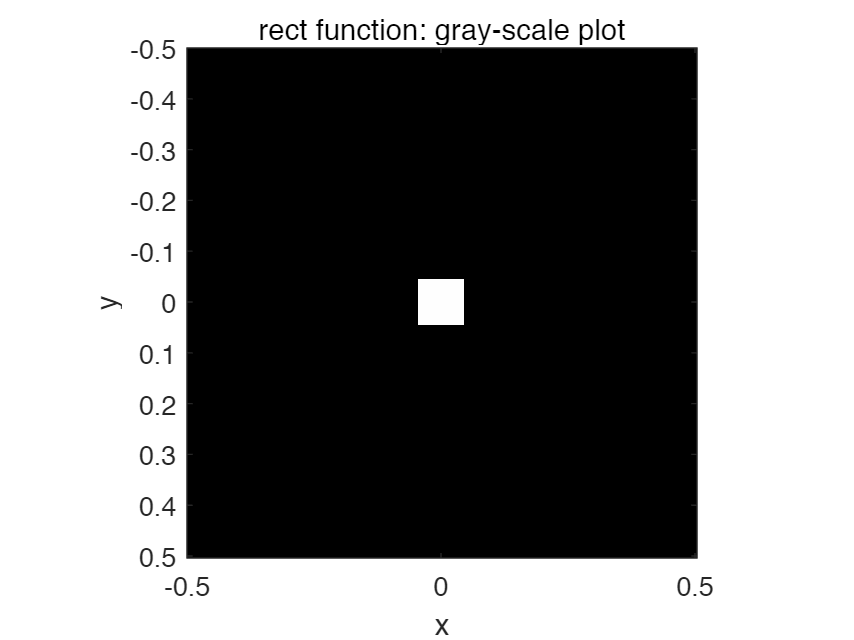

% fft2Drect.m
% Simulation of Fourier transformation of a 2-D rect function% 
clc;
clear;
close all;

L=1; %display area is L by L, L has unit of length
N=256; % number of sampling points 
dx=L/(N-1); % dx : step size

% Create square image, M by M square, rect(x/a,y/a), M=odd number 
M=input ('M (size of rect(x/a,y/a), enter odd numbers from 3-33)=');
a=M/256;
kx0=2*pi/a;
sprintf('a = %0.5g[unit of length]',a);
sprintf('kx0 (first zero)= %0.5g[radian/unit of length]',kx0);
R=zeros(256); % assign a matrix (256x256) of zeros
r=ones(M); % assign a matrix (MxM) of ones
n=(M-1)/2;
R(128-n:128+n,128-n:128+n)=r;
% End of creating square input image M by M

% Axis Scaling
% 对X，Y，Kx，Ky进行坐标轴的缩放，使其与L和dx相匹配。
for k=1:256 
    X(k)=1/255*(k-1)-L/2; 
    Y(k)=1/255*(k-1)-L/2; 
    % Kx=(2*pi*k)/((N-1)*dx) 
    % in our case, N=256, dx=1/255
    Kx(k)=(2*pi*(k-1))/((N-1)*dx)-((2*pi*(256-1))/((N-1)*dx))/2;
    Ky(k)=(2*pi*(k-1))/((N-1)*dx)-((2*pi*(256-1))/((N-1)*dx))/2; 
end 

% Image of the rect function
figure(1);
image(X+dx/2,Y+dx/2,255*R);
title('rect function: gray-scale plot');
xlabel('x');
ylabel('y');
colormap(gray(256));
axis square

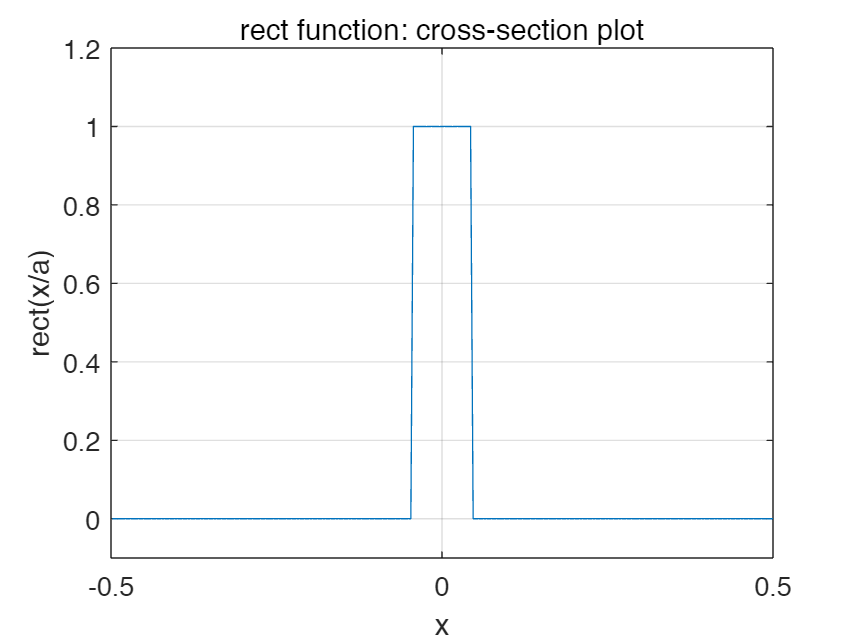


% Computing Fourier transform 
FR=(1/256)^2*fft2(R);
% 对矩形函数进行二维傅里叶变换，并乘以一个归一化因子
FR=fftshift(FR);
% 对频谱进行平移，使其原点在(128,128)
% 利用fft2函数对矩形函数进行二维傅里叶变换，得到其复数形式的频谱。
% 由于fft2函数默认以(1,1)为原点，而我们需要以(128,128)为原点，
% 所以我们使用fftshift函数对频谱进行平移。

% plot of cross-section of rect function
figure(2);
plot(X+dx/2,R(:,127));
title('rect function: cross-section plot');
xlabel('x');
ylabel('rect(x/a)');
grid;
axis([-0.5 0.5 -0.1 1.2]);

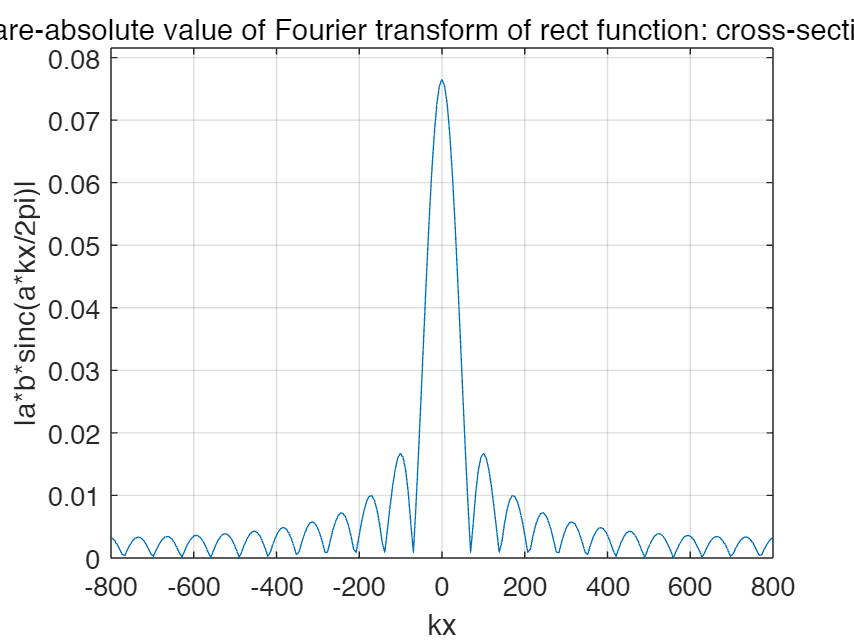


% Centering the axis and plot of cross-section of transform along kx
% 绘制出傅里叶变换后的频谱的横截面图，即在ky=0处的一维函数图像
figure(3);
plot(Kx-pi/(dx*(N-1)),10*abs(FR(:,127)));
% 绘制频谱的幅度的横截面图，并对Kx坐标进行平移，乘以一个放大因子10 
title('Square-absolute value of Fourier transform of rect function: cross-section plot');
xlabel('kx');
ylabel('|a*b*sinc(a*kx/2pi)|')
axis([-800 800 0 max(max(abs(FR)))*10.1]);
grid;

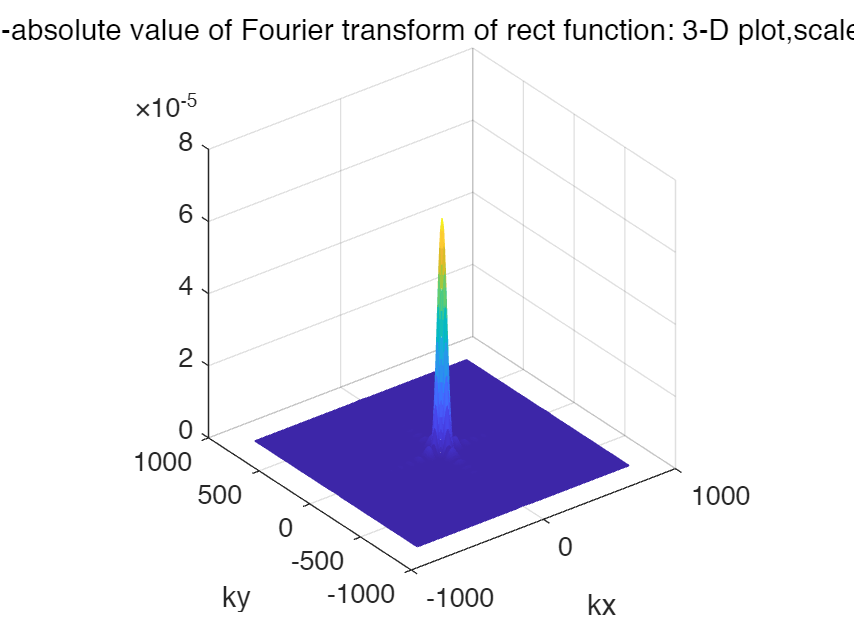


% Mesh the Fourier transformation
% 绘制出傅里叶变换后的频谱的三维图像，即在kx和ky平面上的二维函数图像
figure(4);
mesh(Kx,Ky,(abs(FR)).^2);
% 绘制频谱的幅度的平方的三维图像
title('Square-absolute value of Fourier transform of rect function: 3-D plot,scale arbitrary');
xlabel('kx');
ylabel('ky');
axis square;

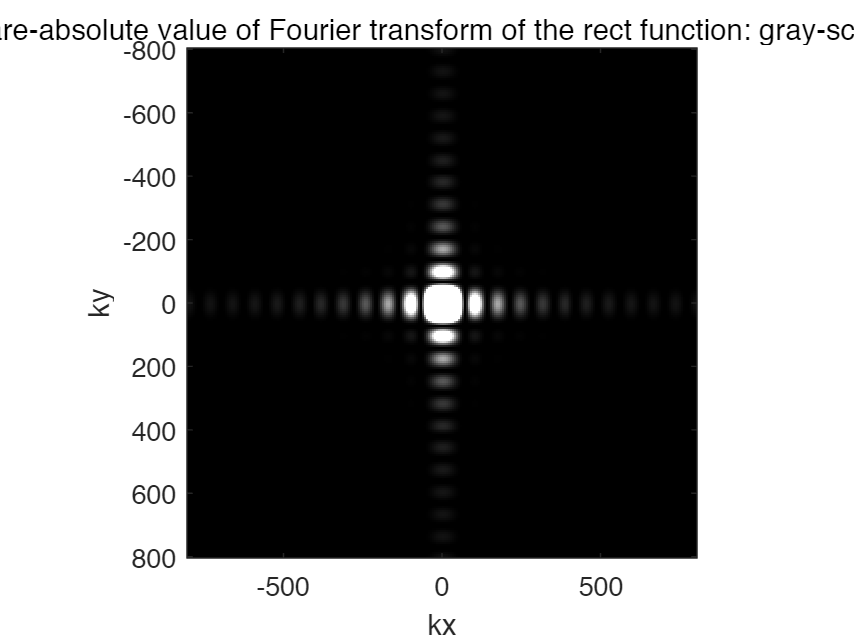


% Image of the Fourier transformation of rectangular function
% 绘制出傅里叶变换后的频谱的灰度图像，即在kx和ky平面上的二维函数图像
figure(5);
gain=10000;
image(Kx,Ky,gain*(abs(FR)).^2/max(max(abs(FR))).^2)
% 利用image函数绘制出频谱的幅度的平方的灰度图像，由于幅度的值比较小，所以乘以一个放大因子gain。
title('Square-absolute value of Fourier transform of the rect function: gray-scale plot');
xlabel('kx');
ylabel('ky');
axis square;
colormap(gray(256));

# Fourier Transform of Bitmap Images

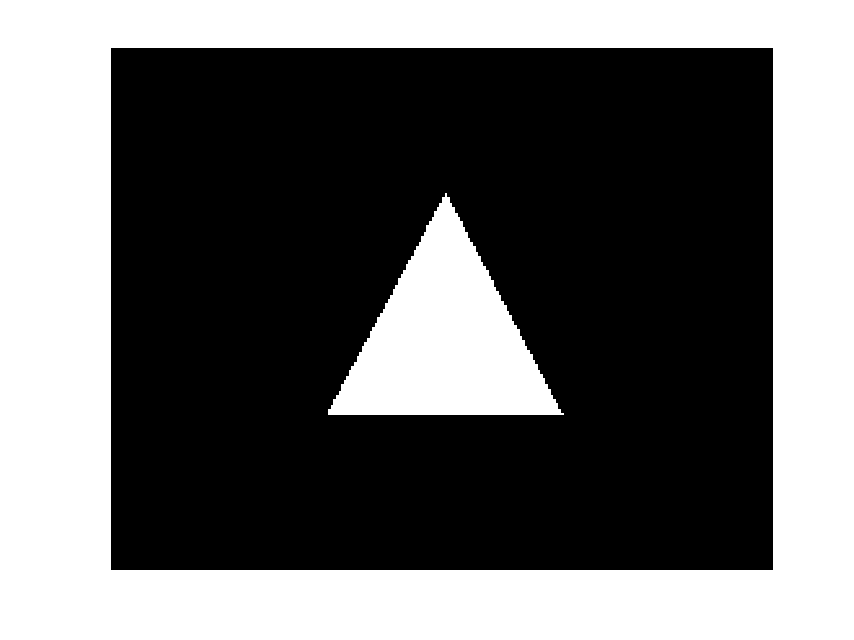

%fft2Dbitmap_image.m
%Simulation of Fourier transformation of bitmap images
clc;
clear;
close all;

I=imread('triangle.bmp','bmp');% Input bitmap image
I=I(:,:,1);
figure(1) % displaying input
colormap(gray(255));
image(I);
axis off;
FI=fft2(I);
FI=fftshift(FI);
max1=max(FI);
max2=max(max1);
scale=1.0/max2;
FI=FI.*scale;
figure(2) % Gray scale image of the absolute value of transform
colormap(gray(255));

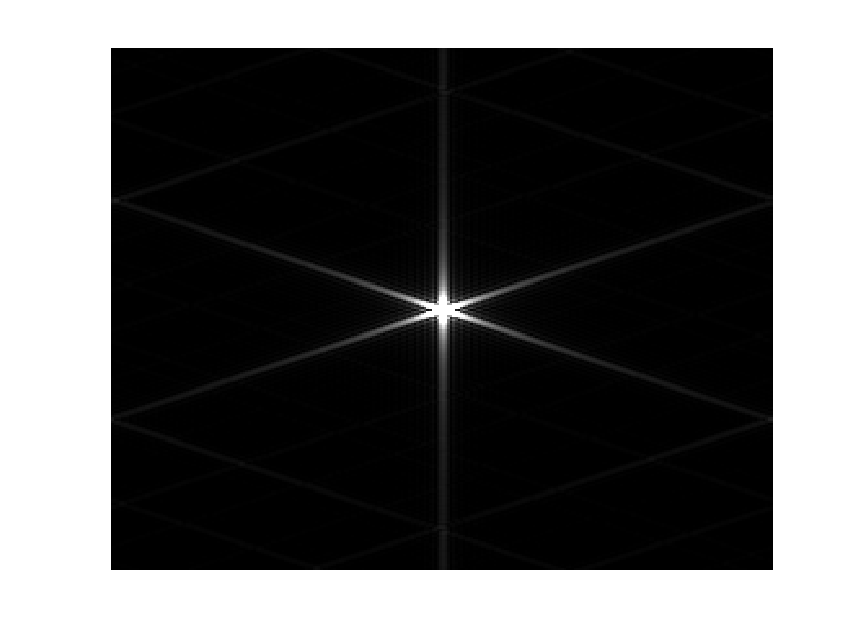

image(10*(abs(256*FI)));
axis off;

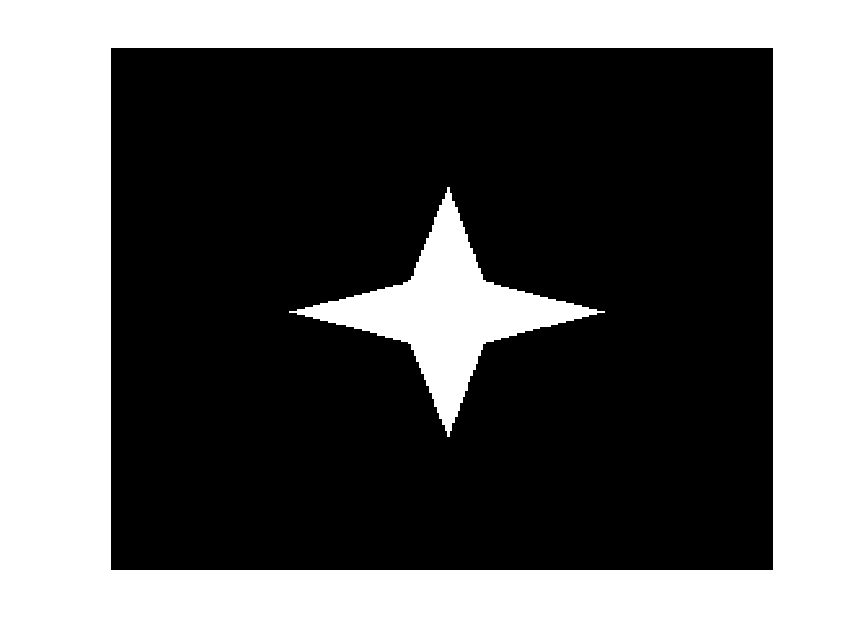

%fft2Dbitmap_image.m
%Simulation of Fourier transformation of bitmap images
clc;
clear;
close all;

I=imread('test1.bmp','bmp');% Input bitmap image
I=I(:,:,1);
figure(1) % displaying input
colormap(gray(255));
image(I);
axis off;

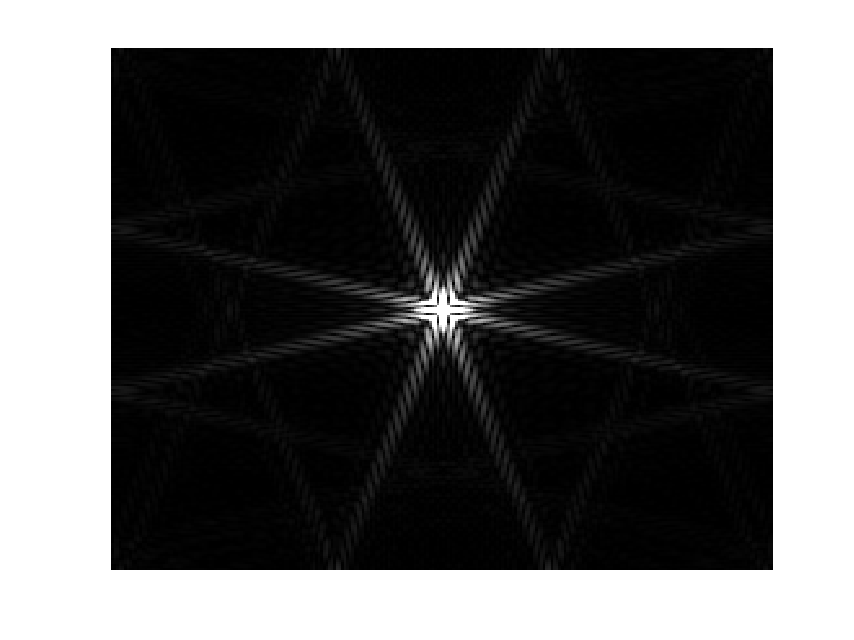

FI=fft2(I);
FI=fftshift(FI);
max1=max(FI);
max2=max(max1);
scale=1.0/max2;
FI=FI.*scale;
figure(2) % Gray scale image of the absolute value of transform
colormap(gray(255));
image(10*(abs(256*FI)));
axis off;

# Pattern Recognition

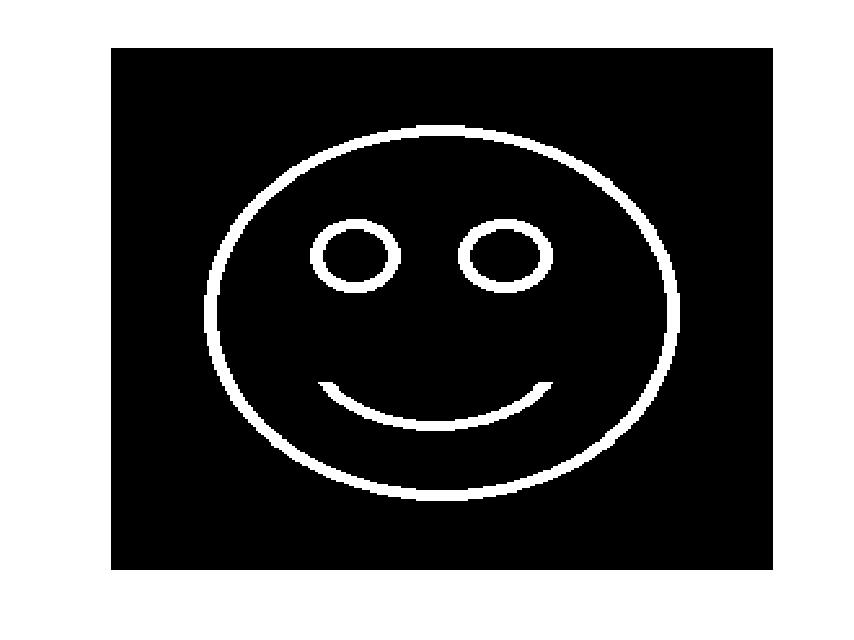

%correlation.m
clc;
clear;
close all;

I1=imread('smiley.bmp','bmp'); % Input image 1 (reference image)
I1=I1(:,:,1);
figure(1);% displaying input image 1
colormap(gray(255));
image(I1);
axis off;


FI1=fft2(I1);
max1=max(FI1);
max2=max(max1);
scale=1.0/max2;
FI1=FI1.*scale;

I2=imread('smiley.bmp','bmp'); % Input image 2 (image to be recognized)
I2=I2(:,:,1);
figure(2) % displaying input image 2
colormap(gray(255));
image(I2);
axis off;

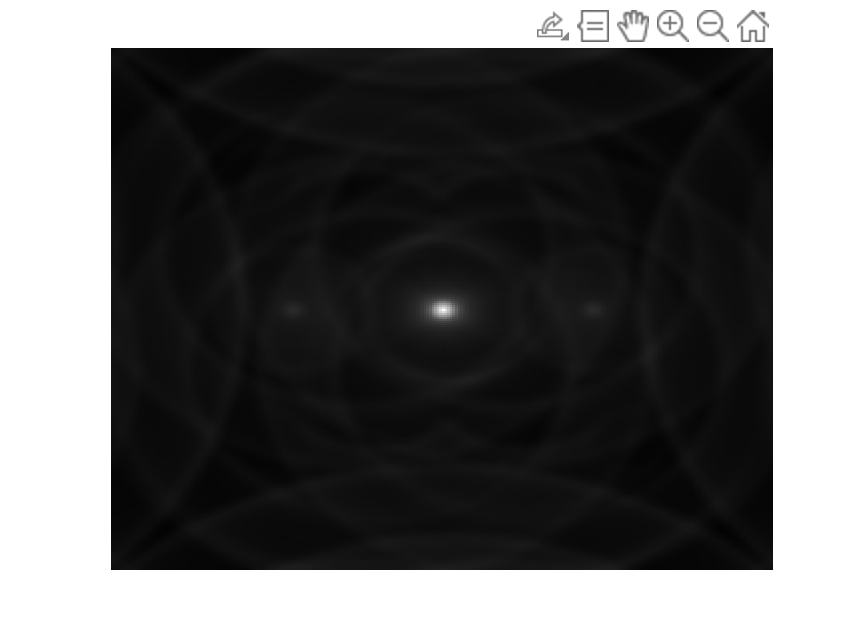


FI2=fft2(I2);
max1=max(FI2);
max2=max(max1);
scale=1.0/max2;
FI2=FI2.*scale;

FPR=FI1.*conj(FI2);% calculating correlation
PR=ifft2(FPR);
PR=fftshift(PR);

max1=max(PR);
max2=max(max1);
scale=1.0/max2;
PR=PR.*scale;

figure(3)% display of correlation in spatial domain
colormap(gray(255));
image(abs(256*PR));
axis off;